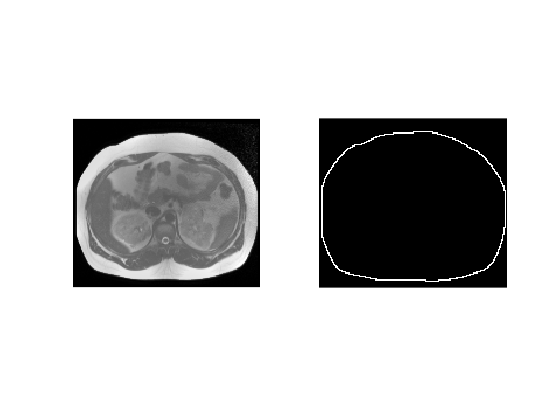

%Load the dataset and show the images with their segmentations
data1 = load("dataForNN_foreBorder_clip0.mat");
data2 = load("dataForNN_foreBorder_clip1.mat");
data3 = load("dataForNN_inside_clip0.mat");

figure();
subplot(1, 2, 1), imshow(data1.trainingImage, []);
subplot(1, 2, 2), imshow(data1.trainingSegmentation, []);

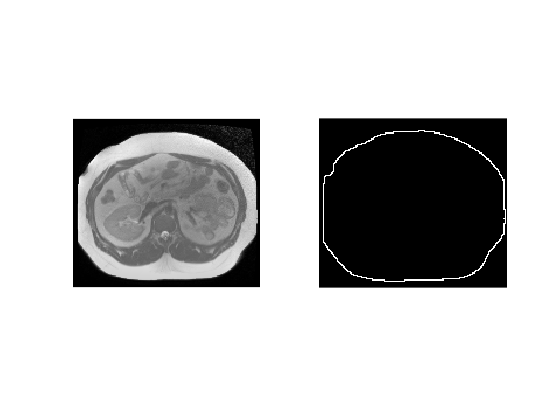


figure();
subplot(1, 2, 1), imshow(data1.testImage, []);
subplot(1, 2, 2), imshow(data1.testSegmentation, []);

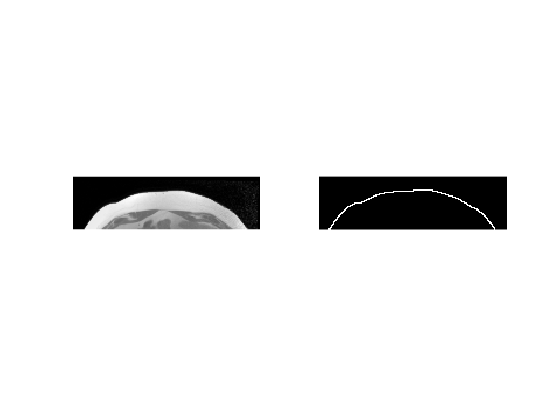



figure();
subplot(1, 2, 1), imshow(data2.trainingImage, []);
subplot(1, 2, 2), imshow(data2.trainingSegmentation, []);

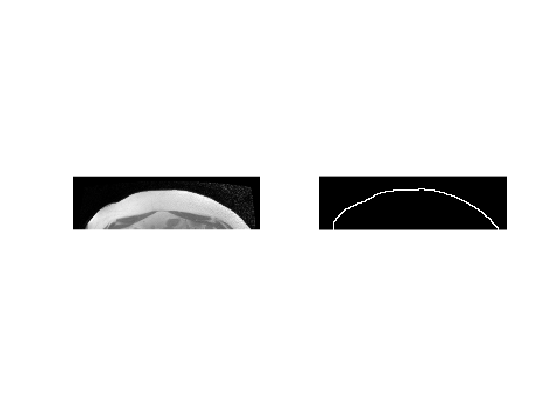


figure();
subplot(1, 2, 1), imshow(data2.testImage, []);
subplot(1, 2, 2), imshow(data2.testSegmentation, []);

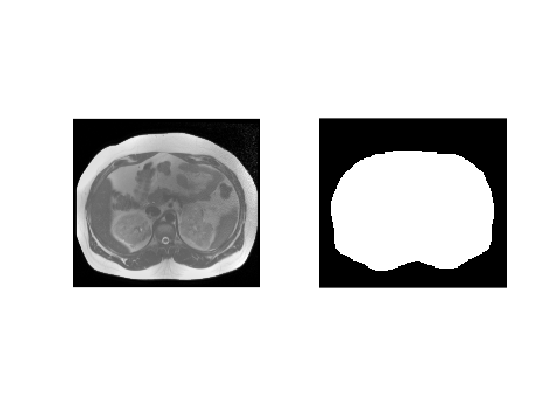


figure();
subplot(1, 2, 1), imshow(data3.trainingImage, []);
subplot(1, 2, 2), imshow(data3.trainingSegmentation, []);

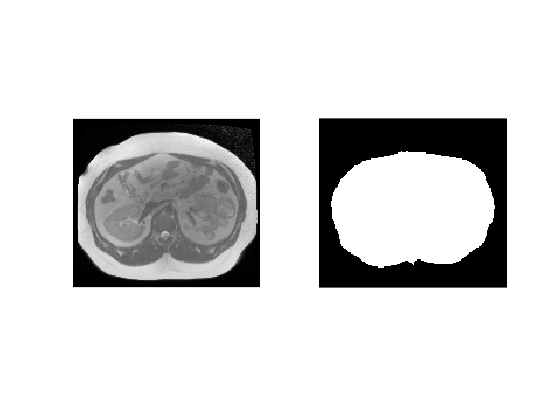


figure();
subplot(1, 2, 1), imshow(data3.testImage, []);
subplot(1, 2, 2), imshow(data3.testSegmentation, []);

%Define Beta vector
Beta = zeros([1, 6]);
ImTrain = data1.trainingImage;
ImSegm = data1.trainingSegmentation;
stepSize = 0.005;

for k = 1:5000
    cost = getCost(Beta, ImTrain, ImSegm, 200);
    delta = 0.001;
    Gradient = zeros(size(Beta));
    if (k < 10)
        disp(cost);
    end
    for i = 1:length(Beta)
        newBeta = Beta;
        newBeta(i) = newBeta(i) + delta;
        newCost = getCost(newBeta, ImTrain, ImSegm, 200);
        Gradient(i) = (newCost - cost) / delta;
    end
    if (k < 10)
        disp(Gradient)
    end
    Beta = Beta - stepSize * Gradient;
end

  138.6294



   98.0250   13.6017  -22.0779    7.3538   47.3301   50.4656



   81.3405



   1.0e+03 *

   -2.0501    0.7349   -2.1701    0.4252    1.6521   -0.5580



   1.4742e+03



   1.0e+05 *

    0.3764    0.3688   -3.2541   -2.1643   -0.1040   -1.1550



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



   NaN



   NaN   NaN   NaN   NaN   NaN   NaN



disp(Beta);

   NaN   NaN   NaN   NaN   NaN   NaN

